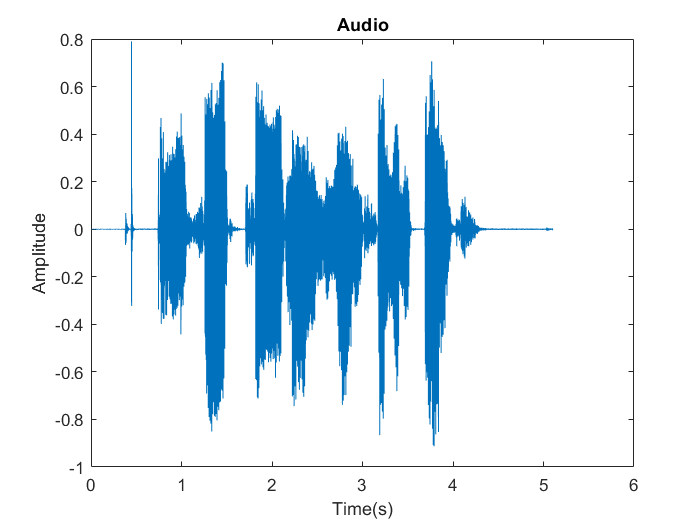

close all;
clear;
filename = "C:\Users\sridh\Documents\MATLAB\DSP\Assignment2\audio\sm4.wav";
[signal,Fs] = getAudio(filename);
t = (0:(length(signal)-1))/Fs;
plot(t,signal); xlabel("Time(s)"); ylabel("Amplitude"); title("Audio");


%t = (0:(length(signal)-1))/Fs;
fsignal = noisefilt(signal,Fs);

nmean = 4.8930e-05

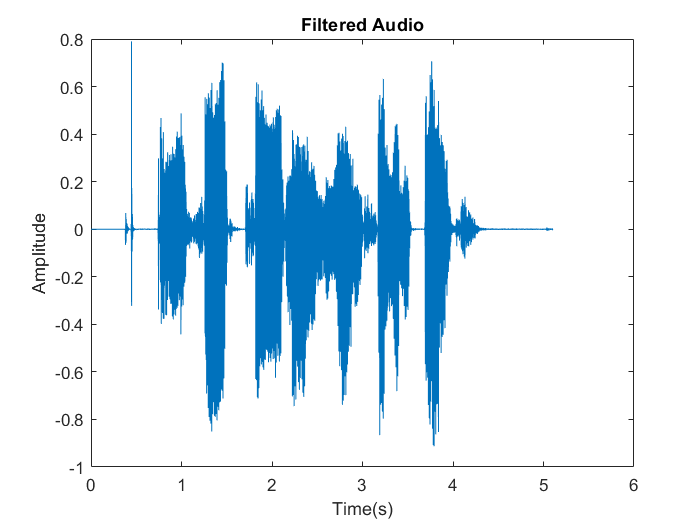

plot(t,fsignal); xlabel("Time(s)"); ylabel("Amplitude"); title("Filtered Audio");

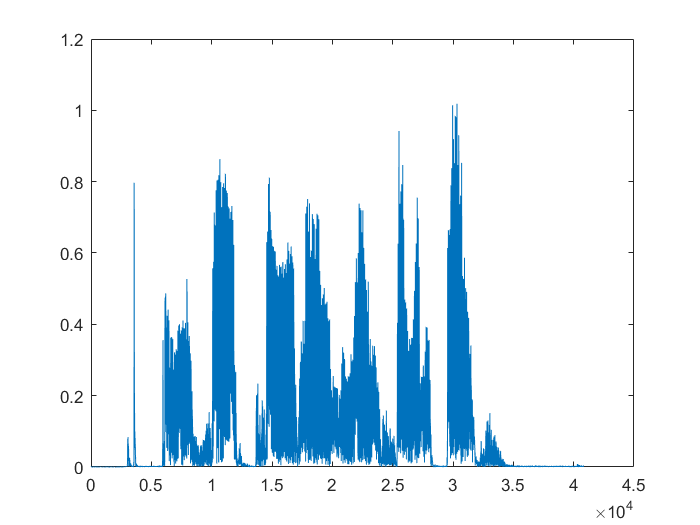


env = hilbert(signal);
plot(abs(env));

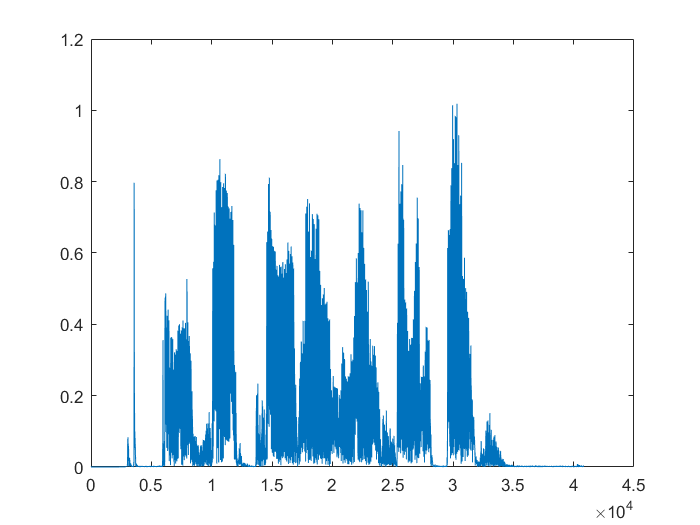

env2 = hilbert(fsignal);
plot(abs(env2));

numberOfBands = 10;


function [x,Fs] = getAudio(name)
Fs = 8000;  %Sampling ratio given
[audio,fs] = audioread(name);
downratio = floor(fs/Fs);
Fs = fs/downratio;  %Might not be exact required frequency
x = downsample(audio,downratio);
end

function [y] = noisefilt(x,Fs)
n = 0.15*Fs;
%if shouvik's file, increase this length
nmean = mean(abs(x(1:n)))
for i = 1:(length(x))
    if(abs(x(i))<5*nmean)
        y(i) = 0;
    else
        y(i) = x(i);
    end
end
end


